%Inputs - x and y vectors

x=[0.4,0.8,1.2,1.6,2.0,2.3];
%y=[0.4,0.8,1.2,1.6,2.0,2.3];
y=[750,1000,1400,2000,2700,3750];

%Process - Use the corresponding regression formulas & variables transformations for
%the exponential regression

n = length(x);
a1 = (n*sum(x.*log(y))-sum(x)*sum(log(y)))/(n*sum(x.^2)-sum(x)^2);
a0 = mean(log(y))-a1*mean(x);

A = exp(a0);
B = a1;

f = @(x) A*exp(B*x);


%Output - display results
% a0 a1 A B

disp("a0 = "+a0)

a0 = 6.2529


disp("a1 = "+a1)

a1 = 0.84172


disp("A = "+A)

A = 519.4969


disp("B = "+B)

B = 0.84172



disp("y="+A+"e^("+B+"x)");

y=519.4969e^(0.84172x)


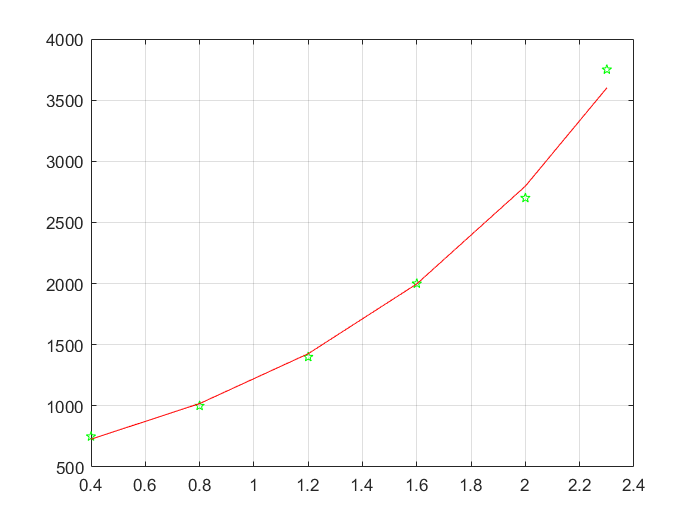


% GRAPH
figure
plot(x, y, 'pg')
hold on
plot(x, f(x), '-r')
hold off
grid

% GRAPH
